# Exam 2016

## Problem 1

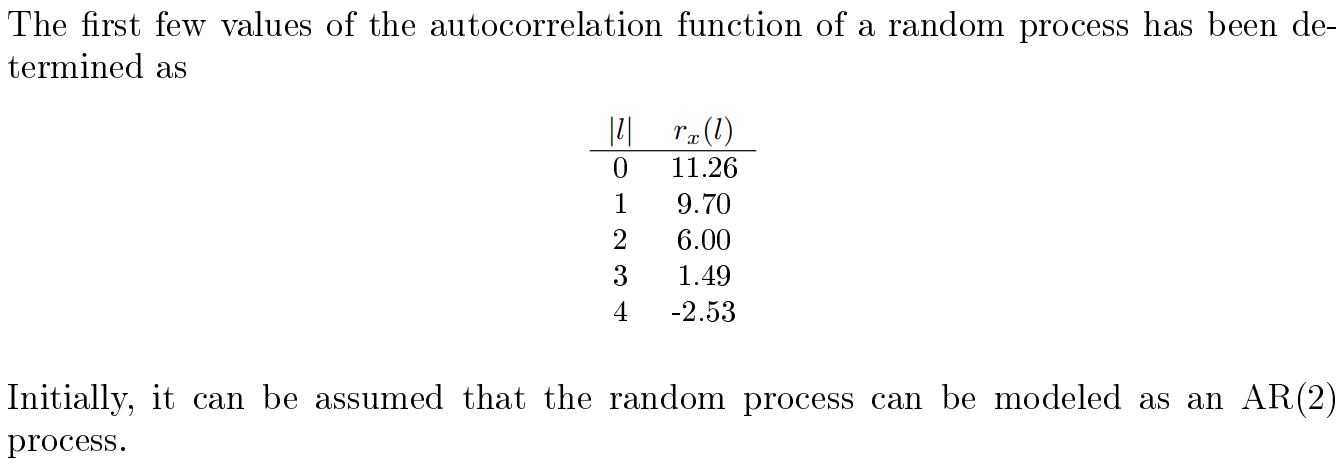

clear variables;

### 1) Compute AR(2) model coefficient given autocorrelation sequence

An AR(p) model is given by:

        
$$y\left(n\right)=-\sum_{k=1}^p \left\lbrack a_k \;y\left(n-k\right)\right\rbrack +b_0 x\left(n\right)$$


The autocorrelation of AR(q) model was derived in Eq. 13.141 as:

        
$$r_{\mathrm{yy}} \left(\ell \right)=-\sum_{k=1}^p a_k r_{\mathrm{yy}} \left(\ell -k\right),\;\;\;\ell >0$$
 

This is useful because we can use it to find the coefficients $\left\lbrace a_k \right\rbrace$ of an AR(q) model using the autocorrelation $r_{\mathrm{yy}} \left(\ell \right)$ computed numerically in MATLAB. This means that the expression in Eq. 13.141 becomes a set of $p$ linear equations.

An AR(2) model is given by:

        
$$y\left(n\right)=-\left(a_1 \;y\left(n-1\right)+a_2 \;y\left(n-2\right)\right)+b_0 x\left(n\right)$$


We can estimate the model parameters of a second-order AR model$p=2$ by creating two equations with two unknowns:

        
$$r_{\mathrm{yy}} \left(1\right)=-a_1 r_{\mathrm{yy}} \left(0\right)-a_2 r_{\mathrm{yy}} \left(-1\right)$$


        
$$r_{\textrm{yy}} \left(2\right)=-a_1 r_{\textrm{yy}} \left(1\right)-a_2 r_{\textrm{yy}} \left(0\right)$$


We can write it into matrix form using the Toeplitz matrix:

        
$$\left\lbrack \begin{array}{cc}
r_{\mathrm{yy}} \left(0\right) & r_{\mathrm{yy}} \left(-1\right)\\
r_{\mathrm{yy}} \left(1\right) & r_{\mathrm{yy}} \left(0\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_1 \\
a_2 
\end{array}\right\rbrack =-\left\lbrack \begin{array}{c}
r_{\mathrm{yy}} \left(1\right)\\
r_{\mathrm{yy}} \left(2\right)
\end{array}\right\rbrack$$


In the general case, it becomes:

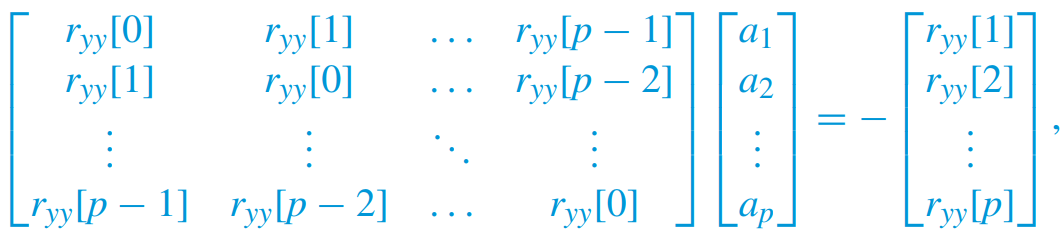

More compactly written as *Yule–Walker equations*:

        

The input noise variance can be compute as follows:

        

This is coded in MATLAB function (see end of document):

p = 2;
r_xx = [11.26, 9.70, 6.00, 1.49, -2.53]';
[a, v] = ar_from_acrs(r_xx, p)

a =    -1.5604
    0.8114


v = 0.9922

The power spectrum of an ARMA(p, q) process is given by:

        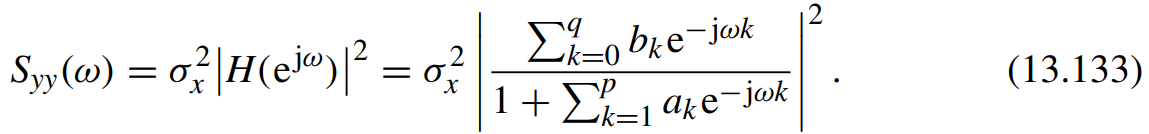

The power spectrum of an AR(p) process is given by:

        
$$S_{\mathrm{yy}} \left(\omega \right)=\sigma_x^2 {\left|\frac{1}{1+\sum_{k=1}^p a_k e^{-j\omega k} }\right|}^2$$


To solve this problem, the method is as follows:

- Find the coefficents $\left\lbrace a_1 ,a_2 ,\cdots ,a_p \right\rbrace$ for the$\mathrm{AR}\left(p\right)$ model

- Compute the transfer function for the $\mathrm{AR}\left(p\right)$ by computing the sum and finding its reciprocal

- Compute the conjugate of the transfer function: ${\left|H\left(e^{j\omega } \right)\right|}^2$

- Multiply it with the variance $\sigma_x^2$

The method above is implemented in the function `ar2psd `(see at the end of document):

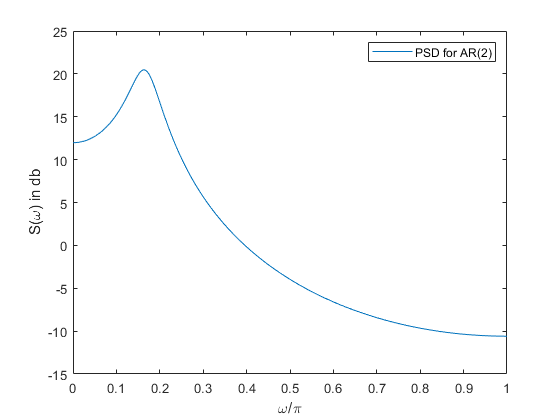

[S, w] = ar2psd(a, v, 256);
plot(w/pi, real(pow2db(S)))
legend('PSD for AR(2)')
xlabel('\omega/\pi')
ylabel('S(\omega) in db')

### 2) Is the random process better modelled as an AR(3) or higher-order process?

The variane $\sigma_x^2$ calculated above corresponds to the minimum Mean Squared Error (MSE) for the AR(2) model. So for a higher order model to be a better model the MSE must be lower than for the AR(2) model. 

We can solve the equations for different AR(q) models:

MSE_ar2 = v

MSE_ar2 = 0.9922

[~, MSE_ar3] = ar_from_acrs(r_xx, 3)

MSE_ar3 = 0.9922

[~, MSE_ar4] = ar_from_acrs(r_xx, 4)

MSE_ar4 = 0.9919

The MSE is lowered very slightly when the model order is increased.

Because of the slight change we can be conclude that the process is not better modeled as an AR(3) or AR(4) process.

## Problem 2: Detect the presence of signal via Matched Filter

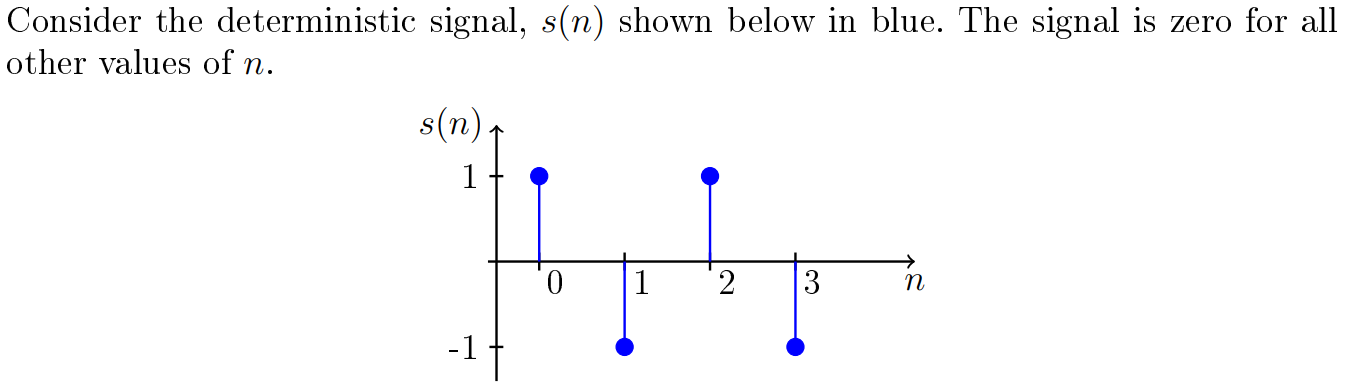

clear variables;


### 1) Design a matched filter for detecting the presence of the signal and calculate the optimum signal to noise ratio.  

The impulse response of the matched filter is given by:

        

where $R_v$ is autocorrelation matrix of noise and $\kappa$ is the normalisation factor. 

Although the maximum SNR can be obtained by any choise of constant $\kappa$, we choose the constant by requiring that:

        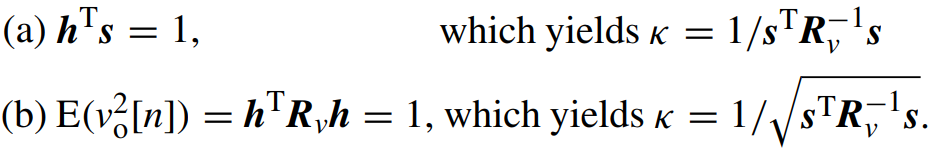

s = [1, -1, 1, -1]';
p = numel(s); % Signal length

% The autocorrelation matrix must be p x p since
% its inverse is multiplied by a p-tap signal s(n)
ell = 0:p-1;
r_vv = 0.3.^ell;
R_vv = toeplitz(r_vv);

% Compute normalisation factor (b)
k = 1/(s'*(R_vv\s));     % Using (a)
% k = 1/sqrt(s'*(R_vv\s)); % Using (b)

% Compute the filter
h = k*(R_vv\s); % Same as k*inv(R_vv)*s

% Print the matched filter coefficients
h

h =     0.2174
   -0.2826
    0.2826
   -0.2174


The optimum SNR at the output is given by:

        

Assuming the attenuation factor $a=1$:

a = 1;
SNR_o = a^2 * s' * (R_vv\s)

SNR_o = 6.5714

  The SNR at the input is given by:

        
$${\mathrm{SNR}}_i =\frac{{\left(\mathrm{Value}\;\mathrm{of}\;\mathrm{signal}\;\mathrm{at}\;n=n_0 \right)}^2 }{\mathrm{power}\;\mathrm{of}\;\mathrm{noise}}=\frac{s^2 \left(n=n_0 \right)}{r_v \left(0\right)}$$


SNR_i = s(1)^2/r_vv(1)

SNR_i = 1

The improvement in SNR is slightly over 6.5.

### 2) Will SNR improve if the longer signal is used?

We can perform the calculations agains:

s = [1, -1, 1, -1, 1, -1]';

p = numel(s); % Signal length
ell = 0:p-1;
r_vv = 0.3.^ell;

R_vv = toeplitz(r_vv);
a = 1;
SNR_o = a^2 * s' * (R_vv\s)

SNR_o = 10.2857

We see that the SNR is increased to 10.3.

So when the signal length is increased, a longer filter can be used. A longer filter implies more signal energy in the filter. Furthermore, the filter can be better tailored to the noise spectrum. Therefore, the signal energy is increased and the noise power is decreased which results in a better SNR.

### 3) Discuss whether the SNR will increase given a different ACRS?

First, we observe that the signal $s\left(n\right)$ us a high-frequency signal because of the alternative sign of the signal. 

The noise process $r_v \left(\ell \right)=0\ldotp 3^{|\ell |}$ is low-frequecy noise. Since the signal is high frequency and the noise is low-frequency, it is easier to separate the signal and the noise.

The another noise process $r_v \left(\ell \right)={\left(-0\ldotp 3\right)}^{\left|\ell \right|}$ is a high-frequency noise. Separating noise from the signal is more difficult due to the overlapping spectra.

We confirm this by calculating the SNR:

s = [1, -1, 1, -1, 1, -1]';
s = flip(s);
p = numel(s); % Signal length
ell = 0:p-1;
r_vv2 = (-0.3).^ell;
R_vv2 = toeplitz(r_vv2);
a = 1;
SNR_o = a^2 * s' * (R_vv2\s)

SNR_o = 3.6923

Characteristics of high-frequency noise ACRS vs low-frequency noise.

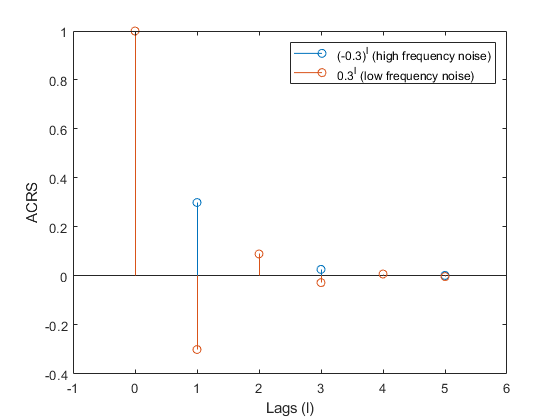

stem(ell, r_vv)
hold on;
stem(ell, r_vv2)
hold off;
legend('(-0.3)^l (high frequency noise)', '0.3^l (low frequency noise)')
xlim([min(ell)-1, max(ell)+1])
hold off;
xlabel('Lags (l)')
ylabel('ACRS')

## Problem 3: Lattice Filters

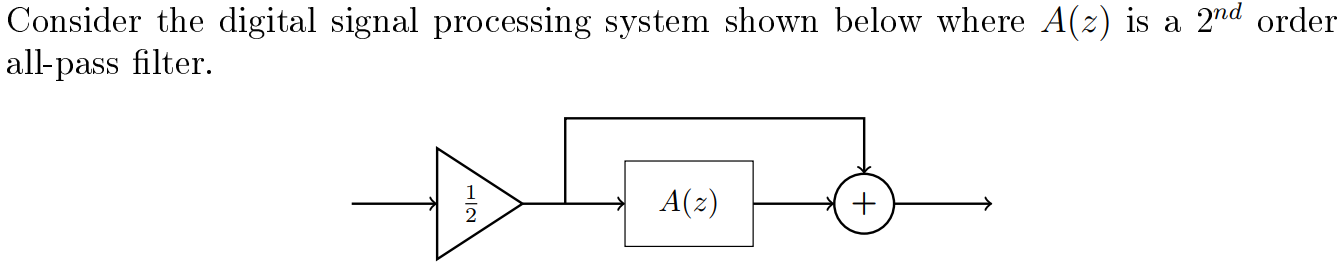

### 1) Explain why a system is a digital notch filter

Since *A*(*z*) is an all-pass filter all frequencies pass un-attenuated but a frequency dependent phase shift is imposed on the signal.

Assume an input signal $x\left(n\right)=\alpha \;\mathrm{cos}\left(\omega n\right)$. If the two signals at the summing point are in phase the output is just equal to the input. For any other phase shift, the two signals will partly cancel out with the degree of cancellation depending on the phase shift.

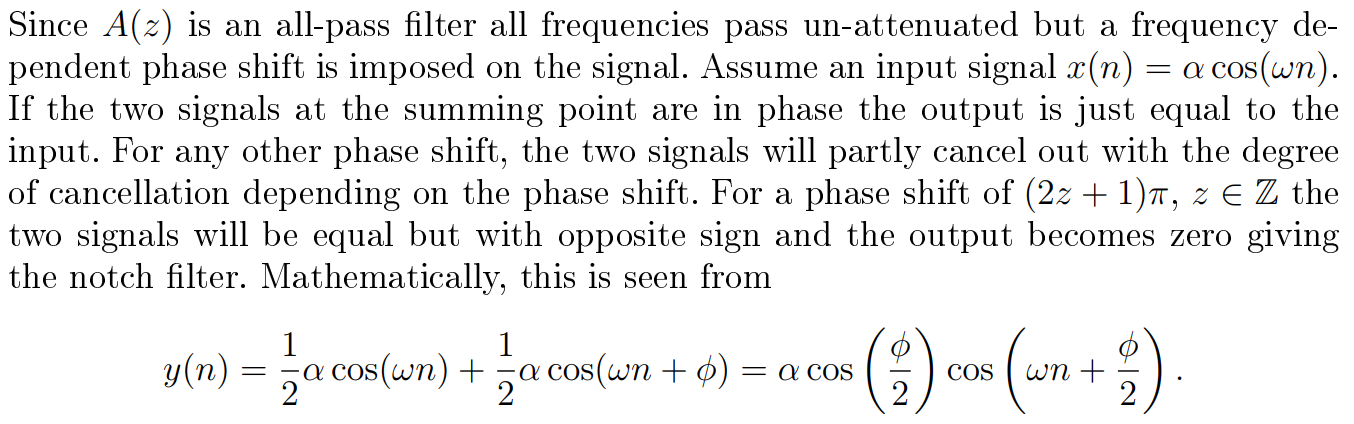

### [?] 2) Find reflection coefficients for the all-pole lattice filter

The all-pass filter can be implemented as an all-pole lattice filter. Assume that

        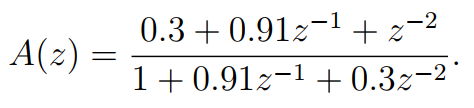

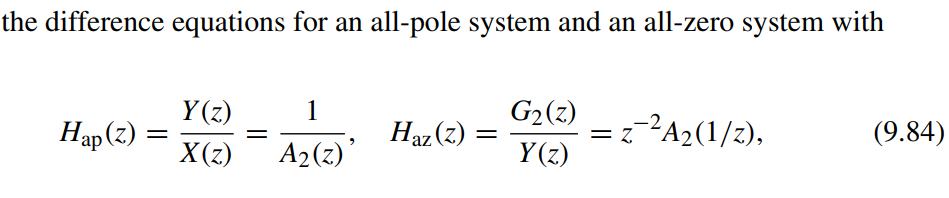

where 

        

From the system function of the all-pass filter, we know that:

        $A_2 \left(z\right)=1+0\ldotp 91z^{-1} +0\ldotp 3z^{-2}$  and $a_2^{\left(2\right)\;} =0\ldotp 3$

... should we continue with this?

### [?] 3) Determine the group delay in the digital notch filter

....

## Problem 4: Random variables

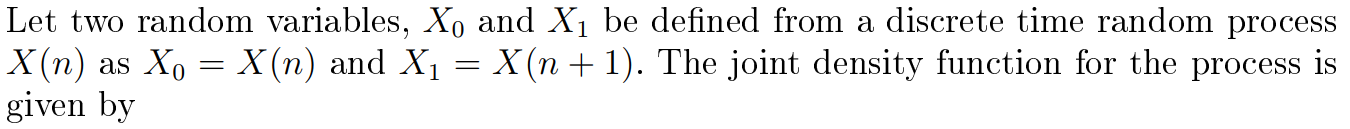

        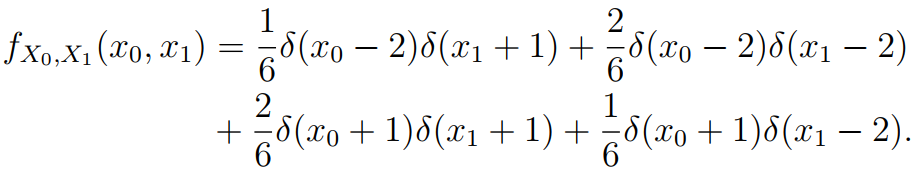

The given joint density function can put in a table where the green cells are the joint probabilities and the blue cells are the marginal probabilities:

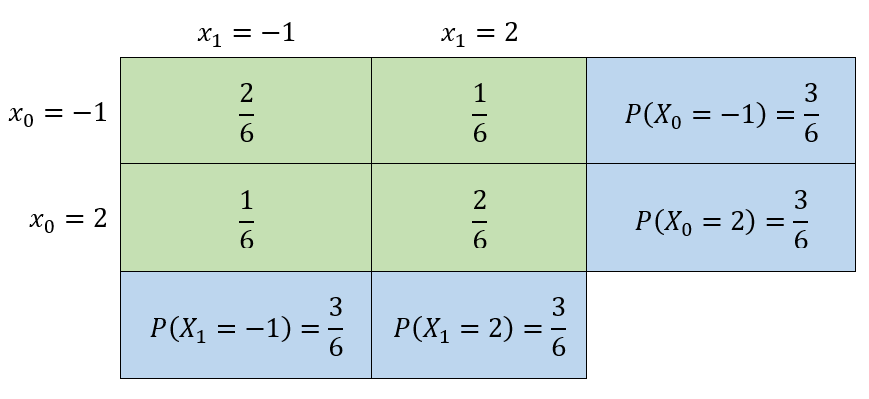

clear variables;

### 1) Sketch a realization of a signal with this density function.

From the joint density function we observe that the signal can take on the two values; +2 or -1.

- If the signal is +2 at $t_0$ then it will go to -1 at $t_0 +1$ with probablity $\frac{1}{6}$

- If the signal is +2 at $t_0$ then it will remain -2 at $t_0 +1$ with probablity $\frac{2}{6}$

- If the signal is -1 at $t_0$ then it will remain -1 at $t_0 +1$ with probablity $\frac{2}{6}$

- If the signal is -1 at $t_0$ then it will go to +2 at $t_0 +1$ with probablity $\frac{1}{6}$

If the signal has the value +2 it has probability $\frac{2}{6}$ for staying at +2 than switching to -1.

If the signal has the value -1 it has probability for staying at -1 than switching to +2.

A realisation coded in MATLAB:

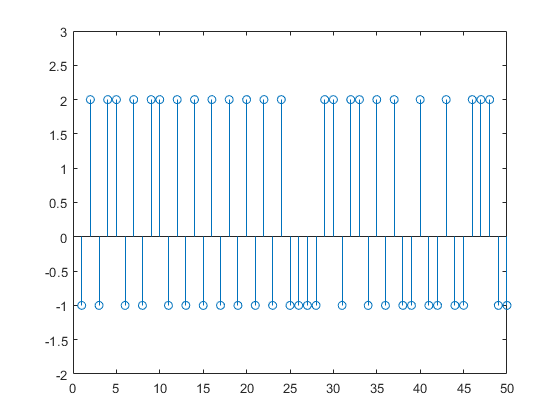

p_pos = 2/6; % The probability to remain when previous value is positive
p_neg = 2/6; % The probability to remain when previous value is negative

pos_val = 2;
neg_val = -1;

N = 50;
x = zeros(1, N);

x(1) = randsrc(1,1, [pos_val, neg_val; 0.5, 0.5]);
for i = 2:N
    if x(i-1) == pos_val
        x(i) = randsrc(1,1, [pos_val, neg_val; p_pos, 1-p_pos]);
    elseif x(i-1) == neg_val
        x(i) = randsrc(1,1, [neg_val, pos_val; p_neg, 1-p_neg]);
    end
end

% stairs(x);
stem(x)
ylim([neg_val-1, pos_val+1]);

### 2) Compute marginal density function

The given joint density function can put in a table where the green cells are the joint probabilities and the blue cells are the marginal probabilities:

The marginal density function is given as:

        
$$f_{X_0 } \left(x_0 \right)=\int_{-\infty }^{\infty } f_{X_0 ,X_1 } \left(x_0 ,x_1 \right)\;{\mathrm{dx}}_1$$


Since the random variables are discrete, the above integral amounts to summing out $X_1$. Doing that we get the required margin mass function:

        
$$f_{X_0 } \left(x_0 \right)=\frac{3}{6}\delta \left(x_0 -2\right)+\frac{3}{6}\delta \left(x_0 +1\right)$$


Alternatively, we can compute:

        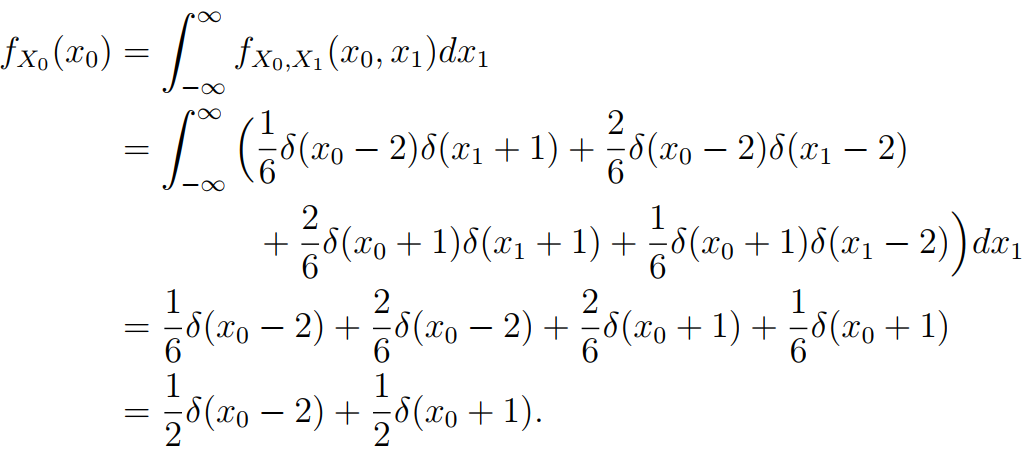

The expected value of a discrete random variable $X$ with outcomes $x_1 ,x_2 ,\cdots ,x_k$is given by:

        
$$E\left(X\right)=\sum_{i=1}^k x_i \;P\left(X=x_i \right)$$


In this problem, we have

        
$$E\left(X_0 \right)=-1\cdot P\left(X_0 =-1\right)+2\cdot P\left(X_0 =2\right)=-1\cdot \frac{1}{2}+2\cdot \frac{1}{2}=\frac{1}{2}$$


Alternative way:

        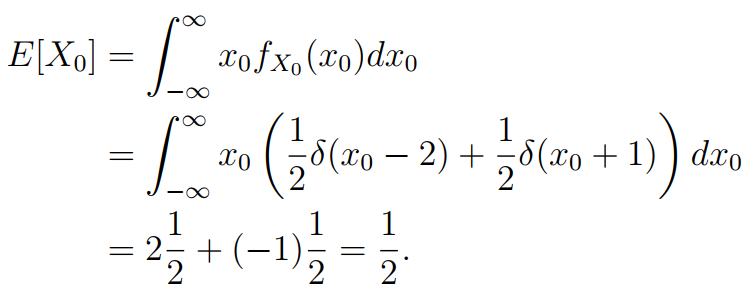

### 3) Determine whether signal is deterministic or random by calculating the correlation.

The correlation can be calculated as:

        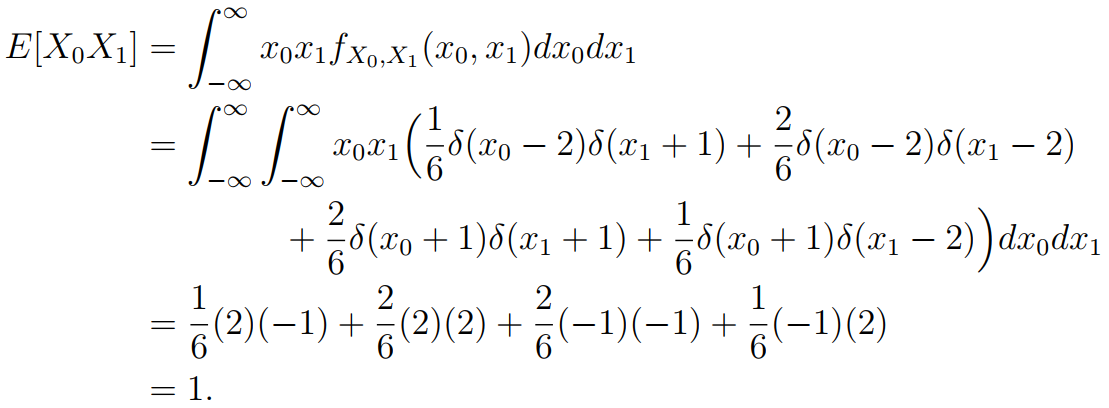

Since there is a non-zero correlation between the signal at time *n *and *n *+ 1 this means that the signal is predictable. The signal is only partially and not perfectly predictable as evident from the above discussion, i.e. the signal is twice as likely to stay at the same value as to switch value. The full classi�cation is thus **partly deterministic**.

## Functions

function [a,v] = arfit(x,p)
    % fit AR(p) model from data
    % x: data
    % p: model order
    % a: a coefficients
    % v: variance
    if isrow(x)
        x = x'; % Convert to a column vector
    end
    
    % Compute the autocorrelation
    [r_xx, lags] = xcorr(x, p, 'biased');
    
    % Select elements r_xx[0] to r_xx[p-1]
    R_elems = r_xx(p+1:2*p);
    
    % Create the Toeplitz matrix
    R = toeplitz(R_elems);
    
    % Select elements r_xx[1] to r_xx[p]
    r = r_xx(p+2:2*p+1);
    
    % Solve systems of linear equations using mldivide function
    a = mldivide(R, -r);
    
    % Compute the variance
    v = r_xx(p+1) + a'*r;
end

function [a, v] = ar_from_acrs(r_xx, p)
    R_xx = toeplitz(r_xx(1:p));
    
    % Select elements r_xx[1] to r_xx[p]
    r = r_xx(2:p+1);
    
    % Solve Yule-Walker equation (13.143)
    a = mldivide(R_xx, -r);
    
    % Compute the variance according to Eq. (13.144)
    v = r_xx(1) + a'*r;
end

function [S, w] = ar2psd(a, v, N)
% AR2PSD Compute the Power Spectral Density from AR(p) coefficients
%   [S, w] = ar2psd(a, v, N)
% a: AR(p) coefficients
% v: the variance
% N: number of points in the range [1, pi]
% S: the estimated power spectrum
% w: frequencies
    w = linspace(0, 1, N) * pi;
    
    % Compute the transfer function
    % Used Eq. (13.133) in the book
    H = ones(N, 1);
    for k=1:numel(a)
        H = H + a(k)*exp(-1j * w' * k);
    end
    H = 1./H;
    
    % Finally compute the PSD
    S = v * H.*conj(H);
end